% %% Simulation input
% %Constant
% b0 = 5e-9; %nT
% q = 1.6e-19; %C
% mion = 1.6605e-27;%kg
% mu0 = 4*pi*10^-7;
% n0 = 5e6; %m^-3
% c = 2.9999*10^8; %km/s
% epsilon0 = 8.85e-12;
% 
% %Simulation Parameters
% dt = 0.05;
% ddthickness = 16;
% thermal = 4;
% T = 155;
% n=200;
% dx_frac = 0.5;
% nx = 100;
% ny = 3;
% nz = 400;
% 
% omega_p = q*b0/mion;
% lambda_i = c/sqrt(n0*q^2/(epsilon0*mion)); %meters
% va = sqrt(b0^2 / (mu0*mion*n0)); %m/s
% 
% z0 = -0.25*ddthickness*lambda_i;
% % %% Grid Initialization
% % %Magnetic Field Grid
% grid_x = 0:lambda_i*dx_frac:(nx*lambda_i);
% grid_y = 0:lambda_i*dx_frac:(ny*lambda_i);
% grid_z = 0:lambda_i*dx_frac:(nz*lambda_i);
% % Bx_slice = 0.5*b0 + 0.5*b0*tanh( (grid_z(nz/2/dx_frac) - grid_z )     / ( lambda_i*dx_frac*ddthickness ) );
% % By_slice = 0.5*b0 + 0.5*b0*tanh( (grid_z - grid_z(nz/2/dx_frac) )     / ( lambda_i*dx_frac*ddthickness ) );
% % Bz_slice = zeros(1,length(Bx_slice));
% B = zeros(length(grid_x),length(grid_y),length(grid_z),3);
% for i=1:length(grid_x)
%     for j=1:length(grid_y)
%         for k=1:length(grid_z)
%             B(i,j,k,1) = 0.5*b0;
%             B(i,j,k,2) = 0.5*b0;
%             if k <= nz/2
%                 B(i,j,k,1) = 0.5*b0*tanh( (grid_z(nz/2/dx_frac) - grid_z(k) )     / ( lambda_i*dx_frac*ddthickness ) );
%                 B(i,j,k,2) = -0.5*b0*tanh( (grid_z(nz/2/dx_frac) - grid_z(k) )     / ( lambda_i*dx_frac*ddthickness ) );
%                 B(i,j,k,3) = 0.0;
%             end
%             if k > nz/2
%                 B(i,j,k,1) = -0.5*b0*tanh( (grid_z(k) - grid_z(nz/2/dx_frac) )     / ( lambda_i*dx_frac*ddthickness ) );
%                 B(i,j,k,2) = 0.5*b0*tanh( (grid_z(k) - grid_z(nz/2/dx_frac) )     / ( lambda_i*dx_frac*ddthickness ) );
%                 B(i,j,k,3) = 0.0;
%             end
%         end
%     end
% end
% 
% plot(squeeze(B(120,2,:,1))/b0,'linewidth',2); hold on
% plot(squeeze(B(120,2,:,2))/b0,'linewidth',2); xlim([0 nz/dx_frac]);
% magneticShear = angle([B(120,2,200,1),B(120,2,200,2),0],[B(120,2,600,1),B(120,2,600,2),0])


clear
%% Simulation input
%Constant
b0 = 5e-9; %nT
q = 1.6e-19; %C
mion = 1.6605e-27;%kg
mu0 = 4*pi*10^-7;
n0 = 5e6; %m^-3
c = 2.9999*10^8; %km/s
epsilon0 = 8.85e-12;

%Simulation Parameters
dt = 0.05;
ddthickness = 16;
thermal = 4;
T = 155;
n=200;
dx_frac = 0.5;
nx = 100;
ny = 3;
nz = 400;

omega_p = q*b0/mion;
lambda_i = c/sqrt(n0*q^2/(epsilon0*mion)); %meters
va = sqrt(b0^2 / (mu0*mion*n0)); %m/s
z0 = -0.25*ddthickness*lambda_i;
% %% Grid Initialization
% %Magnetic Field Grid
grid_x = 0:lambda_i*dx_frac:(nx*lambda_i);
grid_y = 0:lambda_i*dx_frac:(ny*lambda_i);
grid_z = 0:lambda_i*dx_frac:(nz*lambda_i);
B = zeros(length(grid_x),length(grid_y),length(grid_z),3);
shear = 90;
for i=1:length(grid_x)
    for j=1:length(grid_y)
        for k=1:length(grid_z)
            B(i,j,k,1) = cosd(shear/2) * b0 ;
            B(i,j,k,2) = sind(shear/2) * b0;
            if k <= nz/dx_frac/2
                B(i,j,k,1) = B(i,j,k,1) + (cosd(0) - cosd(shear/2))*b0*tanh( (grid_z(nz/2/dx_frac) - grid_z(k) )     / ( lambda_i*dx_frac*ddthickness ) );
                B(i,j,k,2) = B(i,j,k,2) - (          sind(shear/2))*b0*tanh( (grid_z(nz/2/dx_frac) - grid_z(k) )     / ( lambda_i*dx_frac*ddthickness ) );
                B(i,j,k,3) = 0.0;
            end
            if k > nz/dx_frac/2
                B(i,j,k,1) = B(i,j,k,1) - (cosd(shear/2) - cosd(shear) )*b0*tanh( (grid_z(k) - grid_z(nz/2/dx_frac) )     / ( lambda_i*dx_frac*ddthickness ) );
                B(i,j,k,2) = B(i,j,k,2) + ( sind(shear) - sind(shear/2) )*b0*tanh( (grid_z(k) - grid_z(nz/2/dx_frac) )     / ( lambda_i*dx_frac*ddthickness ) );
                B(i,j,k,3) = 0.0;
            end
        end
    end
end

plot(squeeze(B(120,2,:,1))/b0,'linewidth',2); hold on
plot(squeeze(B(120,2,:,2))/b0,'linewidth',2); xlim([0 nz/dx_frac]);
plot(sqrt(squeeze(B(120,2,:,1)).^2 + squeeze(B(120,2,:,2)).^2)/b0,'linewidth',2)
magneticShear = angle([B(120,2,200,1),B(120,2,200,2),0],[B(120,2,600,1),B(120,2,600,2),0])

magneticShear = 90.0000

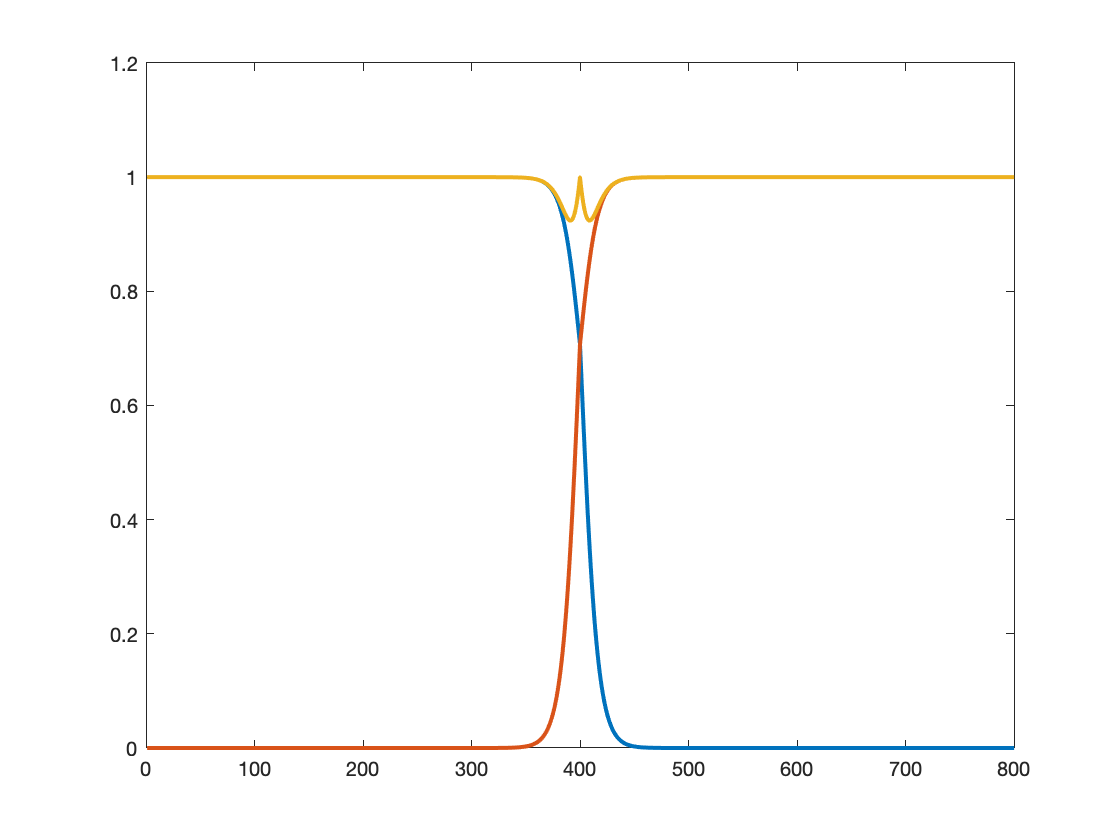

hold off

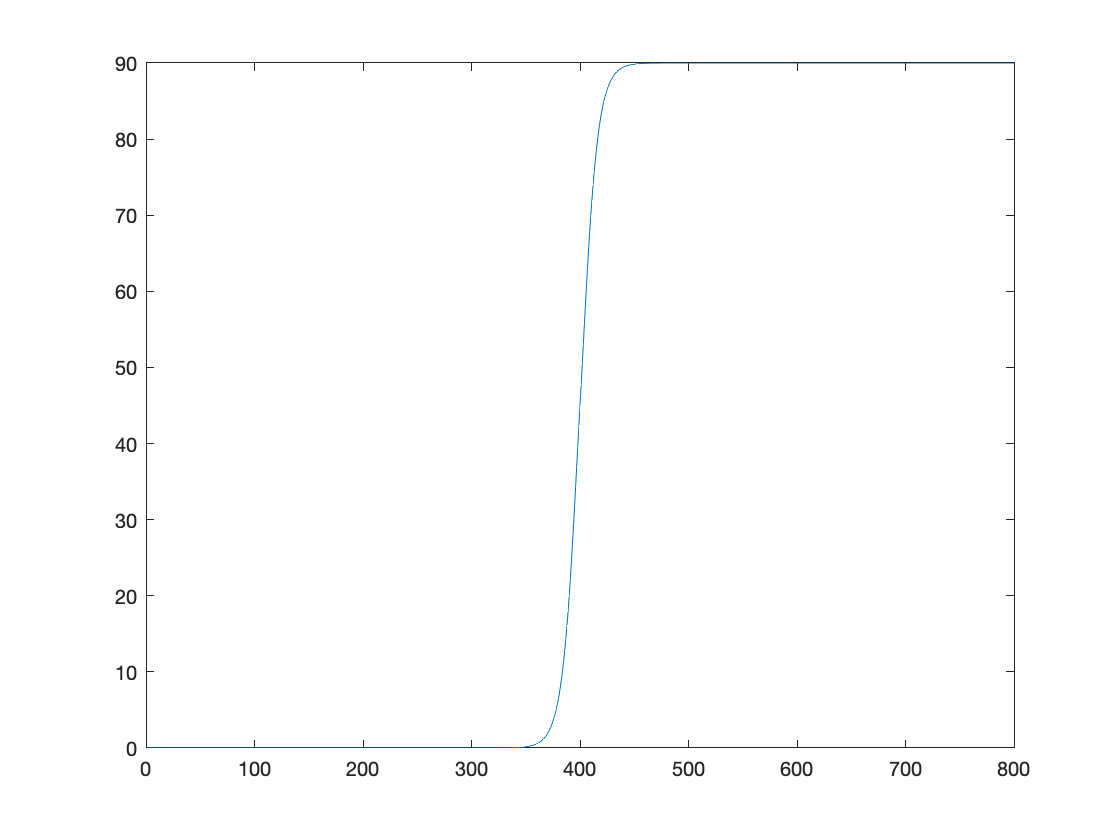

shearEverywhere = [];
for i=1:nz/dx_frac
    shearEverywhere(i) = angle([1,0,0],[B(120,2,i,1),B(120,2,i,2),0]);
end
plot(shearEverywhere)

% shear = 90
% cosd(45)
% my = sind(shear) - sind(shear/2)
% sind(45)
% cosd(shear/2)
% sind(shear/2)
% 
% mx = cosd(shear) - cosd(shear/2)
% my = sind(shear) - sind(shear/2)
% 
% mx + cosd(shear/2)
% mx - cosd(shear/2)